# Decrease Window Length

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the signal.

load ./data/brokenouterrace.mat

## Tasks

The slider in the script controls the number of segments that will be used with Welch's method. For example, a slider value of `2` sets the window length to half of the signal's length so that there will be 2 segments.

To start, the slider value is `1`, so the window is the same length as the signal.

The fluctuations from noise decreased. Before averaging, the noise fluctuations ranged from about -80 dB to -35 dB (about 45 dB of fluctuations).

After dividing the signal into 2 segments, the noise only goes down to about -60 dB to -35 dB (about 25 dB of fluctuations).

The noise floor flattened to about 10 dB of fluctuations.

As you continue to add more segments, the noise floor will get flatter but the frequency resolution will get worse.

numsegments =20

numsegments = 20

winlen = n / numsegments

winlen = 600

w = kaiser(round(winlen),19);

This code plots the spectrum. 

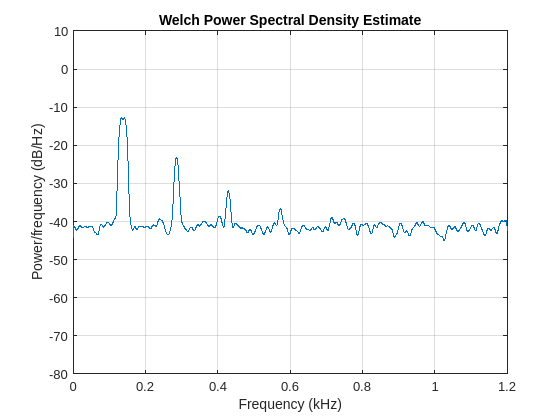

figure;
pwelch(sig,w,0,2^12,fs);
ylim([-80 10])